# This is the live script for ESE 6190 HW7 Explicit, Robust, & Hybrid MPC Exercise 2

clear all
clc

## 2.4-2.6 Consider the Robust Case using additive bounded noise model

## 2.4 design MPC by robustify the state constraints so that the MPC is persistently feasible (open loop robust mpc, not tube mpc), see the function below

## 2.5 Explicit Robust MPC solution

% system dynamics
A = [1.2 1; 0 1];
B = [0; 1];
% state constraints
xmin = [-15; -15];
xmax = [15; 15];
% input constraints
umin = -1;
umax = 1;
% MPC stage costs
Q = eye(2);
R = 1;
% MPC terminal constriants and cost, use LQR
[P,~,K] = dare(A,B,Q,R);
Finf = -K;
Acl = A + B*Finf;
system_Terminal = LTISystem('A',Acl);
Xtilde = Polyhedron('A',[eye(2);-eye(2);Finf;-Finf],'b',[15;15;15;15;1;1]);
% normal maximum invariant set
Oinf = system_Terminal.invariantSet('X',Xtilde);

Iteration 1...
Iteration 2...


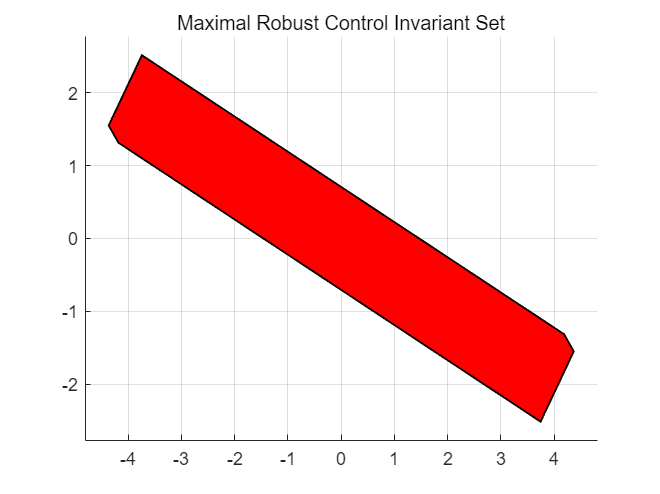

n = size(A, 1);
m = size(B, 2);
%% bounded noise set
dmax = [0.1; 0.1];
dmin = [-0.1; -0.1];
DA = [eye(n); -eye(n)];
Db = [dmax; -dmin];
%% Robust Maximum Invariant Set Calculation
Dtilde = Polyhedron('A',DA,'b',Db);
while true
    Pre_X = invAffineMap(minus(Xtilde,Dtilde),Acl);
    X_new = Pre_X.intersect(Xtilde);
    if X_new == Xtilde
        break
    else
        Xtilde = X_new;
    end
end
figure
plot(Xtilde)
Af = Xtilde.A;
bf = Xtilde.b;
title('Maximal Robust Control Invariant Set')

% MPC horizon
N = 3;
x = sdpvar(2,1);
[U_sol,bf_tight] = mympc_explicit_robust(A,B,Q,R,P,N,umin,umax,xmin,xmax,Af,bf,DA,Db,x);

mpt_plcp: 27 regions


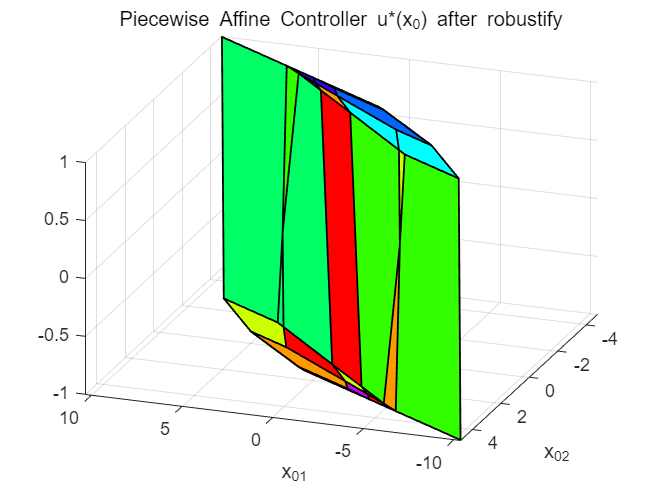

U = U_sol.xopt;
figure
hold on
U.fplot('primal');
title('Piecewise Affine Controller u*(x_0) after robustify')
xlabel('x_{01}')
ylabel('x_{02}')
view([-160 30]);

## 2.6 Simulate 25 closed-loop state trajectory with distrubance

% pre calculate the explicit solution offline
x = sdpvar(2,1);
[U_sol,bf_tight] = mympc_explicit_robust(A,B,Q,R,P,N,umin,umax,xmin,xmax,Af,bf,DA,Db,x);

mpt_plcp: 27 regions


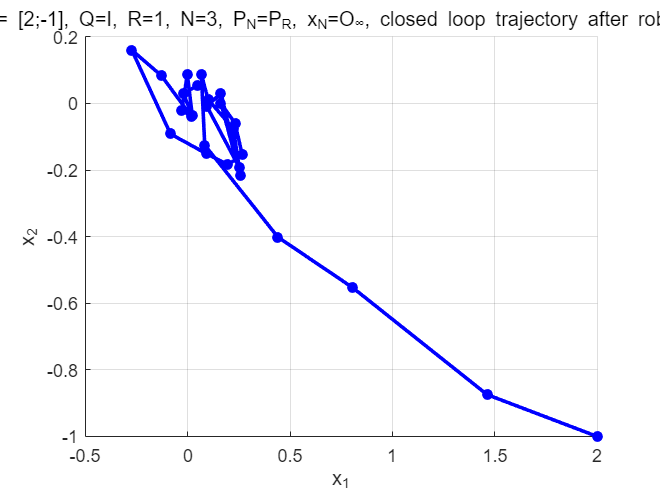

U = U_sol.xopt;
T_sim = 25;
% initial condition
x0 = [2;-1];
% disturbance signal, uniformly sampled
rng(0)
D = -0.1 + 0.2 * rand(2,25);

% record for the plot
n = size(A, 1);
m = size(B, 2);
U_record = zeros(T_sim*m,1);
X_record = zeros(T_sim*n,1);

% do the simulation with explicit lookup online
for i = 1 : T_sim
    if i == 1
        x = x0;
    end
    u = U.feval(x, 'primal');
    u = u(1);
    xp = disturbed_system_sim(x,u,A,B,D(:,i));
    U_record((i-1)*m+1:i*m,1) = u;
    X_record((i-1)*n+1:i*n,1) = xp;
    x = xp;
end
X_record = [x0;X_record];
Xf_tight = Polyhedron('A',Af,'b',bf_tight);
figure;
hold on
grid on
plot(X_record(1:n:end),X_record(2:n:end),'-o','LineWidth',2,'Color','b','MarkerFaceColor','b','MarkerSize',4)
title('x_0 = [2;-1], Q=I, R=1, N=3, P_N=P_R, x_N=O_∞, closed loop trajectory after robustify')
ylabel('x_2')
xlabel('x_1')

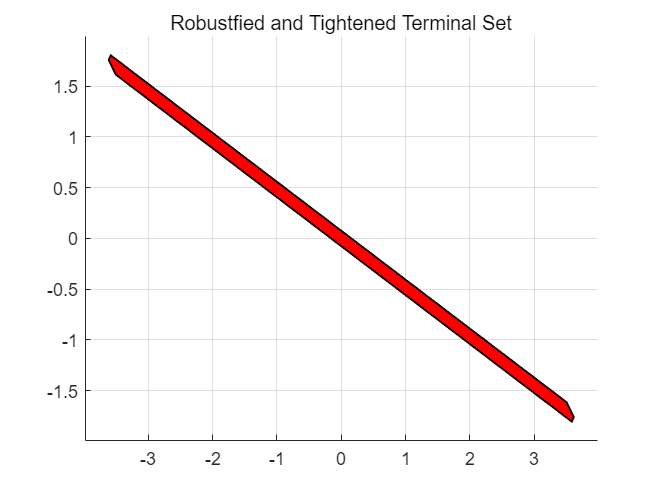

figure;
plot(Xf_tight)
title('Robustfied and Tightened Terminal Set')

## MPC controller function and simulating helper function

function [U_sol,bf_tight] = mympc_explicit_robust(A,B,Q,R,P,N,umin,umax,xmin,xmax,Af,bf,DA,Db,x)
%% This is the function used to solve the linear mpc problem explicitly with open-loop robustness
    %% linear quadratic optimal control via recursive approach
    %% The method is batch-approach based with substitution, i.e. shooting
    %% essentially, it is solving multiparametric QP about initial state x
    %% input:
    %  A: system matrix; B: Input matrix; N: control horizon;
    %  Q,R: weight matrices for states and inputs, respectively;
    %  P: terminal cost weight matrix;
    %  umin,umax: box constraints for control inputs, vectors
    %  xmin,xmax: box constraints for state inputs, vectors
    %  Af, bf: Terminal state constraint (convex polytope region, robust maximal invariant set)
    %  DA, Db, the bounded noise set represented by polytope DA*d<=Db
    %  x: the current state (or say, the initial state for every mpc
    %  planning), should be a sdp variable to do the mp-QP
    %% output:
    %  U_sol: the explicit mp-QP mpc control sequence
    %  bf_tight: tightened terminal state constraints (tightend robust invariant set)

    % first, rollout the dynamics to get Sx(mathcalA) and Su(mathcalB):
    n = size(A, 1);
    m = size(B, 2);
    Sx = zeros((N+1)*n, n);
    Su = zeros((N+1)*n, N*m);
    for i = 0:N
        Sx(i*n+1:(i+1)*n, 1:n) = A^i;
        for j = 0:N-1
            Su(i*n+1:(i+1)*n, j*m+1:(j+1)*m) = (i-j-1>=0)*A^(i-j-1)*B;
        end
    end

    % Then, get the stack-up weight matrices and rearrage as quadratic form
    % Q_bar(mathcal Q) and R_bar(mathcal R)
    I_N = eye(N);
    Q_bar = kron(I_N, Q);
    Q_bar(end+1:end+n, end+1:end+n) = P;
    R_bar = kron(I_N, R);
    H = 2*(Su'*Q_bar*Su + R_bar);
    F = 2*Sx'*Q_bar*Su;
    Y = x'*Sx'*Q_bar*Sx*x;
    
    % add state and input constraints, write them in inequality form
    % here write input constraints also in the stack-up inequality
    % infact, can use quadprog's lb and ub to set the input constraints 
    % since decision variable is u
    % x in (xmin, xmax), u in (umin, umax), xf in (xmin, xmax)
    Ax = [eye(n); -eye(n)];
    bx = [xmax;-xmin];
    Au = [eye(m); -eye(m)];

    % constrauct G block by block, also construct the w_x_block here
    G_u_block = kron(I_N,Au);
    % here 2 because we have 2 states and need to set upper and lower limit for each state
    % for more general case, consider using num_con_x = size(Ax,1)/n
    % i.e. num_con_x = 2 here (upper limit 1, lower limit 1)
    G_x_block = zeros(N*n*2, N*m);
    w_x_block = zeros(N*n*2, 1);

    % robust constraint calculation also included
    options = optimoptions('linprog','Display','off');
    for i = 0:N-1
        % the original state constraint set
        % calculate the propgation of noise set caused by the dynamics
        for k = 0:i-1
            if k == 0
                dyn_prop = Ax*A^0;
            else
                dyn_prop = [dyn_prop, Ax*A^k];
            end
        end
        if i == 0
           support_fun = zeros(size(Ax,1),1);
        else
           DA_block = kron(eye(i),DA);
           Db_block = kron(ones(i,1),Db);
           f = -dyn_prop;
           for l = 1:size(f,1)
               [d,support_fun(l)] = linprog(f(l,:)', DA_block, Db_block,[],[],[],[],options);
           end
        end
        support_fun = -support_fun;
        % the new constraint set should be the pontryagin difference of the
        % state constraint set and noise set (after propagation)
        for j = 0:N-1
            G_x_block(i*2*n+1:(i+1)*2*n, j*m+1:(j+1)*m) = (i-j-1>=0)*Ax*A^(i-j-1)*B;
        end
        w_x_block(i*n*2+1:(i+1)*n*2) = bx - support_fun;
    end

    % num_terminal_constraint = size(Af,1)/n
    num_tc = size(Af,1)/n;
    G_xf_block = zeros(n*num_tc, N*m);
    for j = 0:N-1
        G_xf_block(:, j*m+1:(j+1)*m) = (N-j-1>=0)*Af*A^(N-j-1)*B;
    end
    G = [G_u_block; G_x_block; G_xf_block];

    % construct E block by block
    E_u_block = zeros(N*2, n);
    E_x_block = zeros(N*n*2, n);
    for i = 0:N-1
        E_x_block(i*n*2+1:(i+1)*n*2, 1:n) = -Ax*A^i;
    end
    E_xf_block = -Af*A^N;
    E = [E_u_block;E_x_block;E_xf_block];

    % construct w block by block
    bu = [umax;-umin];
    w_u_block = kron(ones(N,1),bu);
    % also need to shrink the terminal constraint
    for k = 0:N-1
        if k == 0
            dyn_prop = Af*A^0;
        else
            dyn_prop = [dyn_prop, Af*A^k];
        end
    end
    f = -dyn_prop;
    DA_block = kron(eye(N),DA);
    Db_block = kron(ones(N,1),Db);
    for l = 1:size(f,1)
        [d,support_fun(l)] = linprog(f(l,:)', DA_block, Db_block,[],[],[],[],options);
    end
    support_fun = -support_fun;

    bf_tight = bf - support_fun;
    w = [w_u_block;w_x_block;bf_tight];

    % Get the MPC control input from solving the mp-QP
    U = sdpvar(m*N,1);
    J = U'*H*U + 2*x'*F*U;
    C = [G*U <= w+E*x];
    mpQP = Opt(C, J, x, U);
    U_sol = mpQP.solve();
end

function xp = disturbed_system_sim(xk, uk, A, B, dk)
    %% This is the function used to simulate single-step dynamics of the diturbed system
    %% input:
    %  A: system matrix; B: Input matrix;
    %  xk: current state, uk: current input, dk: disturbance signal
    xp = A*xk + B*uk + dk;
end